%% EGB242 In Class Challenge 6 - Skeleton code

clearvars; close all; clc;

%% Reading in audio file
[audioReversed, fs] = audioread('audio1.wav');
% sound(audioReversed, fs)

## Q1) The sound file 'audioReversed' appears to be reversed

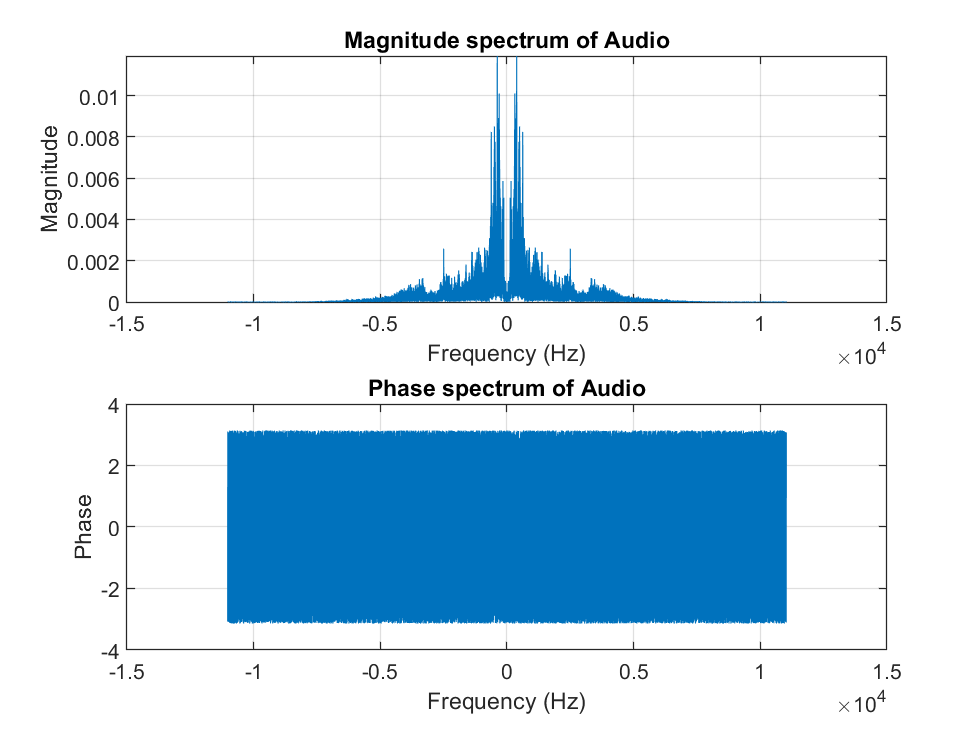

% Transform audio file to frequency domain
Ts = 1 / fs; % seconds / sample

AudioReversed = fftshift(fft(audioReversed)) * Ts;

% Generate frequency vector f for plotting the magnitude spectrum
% in the next step
samples = length(AudioReversed);
f = linspace(-fs / 2, fs / 2, samples + 1); % This is the frequency vector from -fs/2 to fs/2
f(end) = [];

% Plot the magnitude of 'AudioReversed'
figure(1);
subplot(2,1,1);
plot(f, abs(AudioReversed))
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude spectrum of AudioReversed');
grid on;

% Plot the phase of 'AudioReversed'
figure(1)
subplot(2,1,2)
plot(f, angle(AudioReversed))
xlabel('Frequency (Hz)')
ylabel('Phase')
title('Phase spectrum of Audio Reversed')
grid on

% Using the relation found in the question sheet attempt to reverse
% 'AudioReversed' back to normal.

Audio = conj(AudioReversed);

% Plot the magnitude of Audio
figure(2)
subplot(2,1,1)
plot(f, abs(Audio))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude spectrum of Audio')
grid on

% Plot the phase of Audio
subplot(2,1,2)
plot(f, angle(Audio))
xlabel('Frequency (Hz)')
ylabel('Phase')
title('Phase spectrum of Audio')
grid on


% Transform 'Audio' back to the time domain
audio = ifft(ifftshift(Audio) / Ts);

% Listen to audio file using the SOUND function
% sound(audio,fs)

% What can you say about the two plots ?


## Question 2

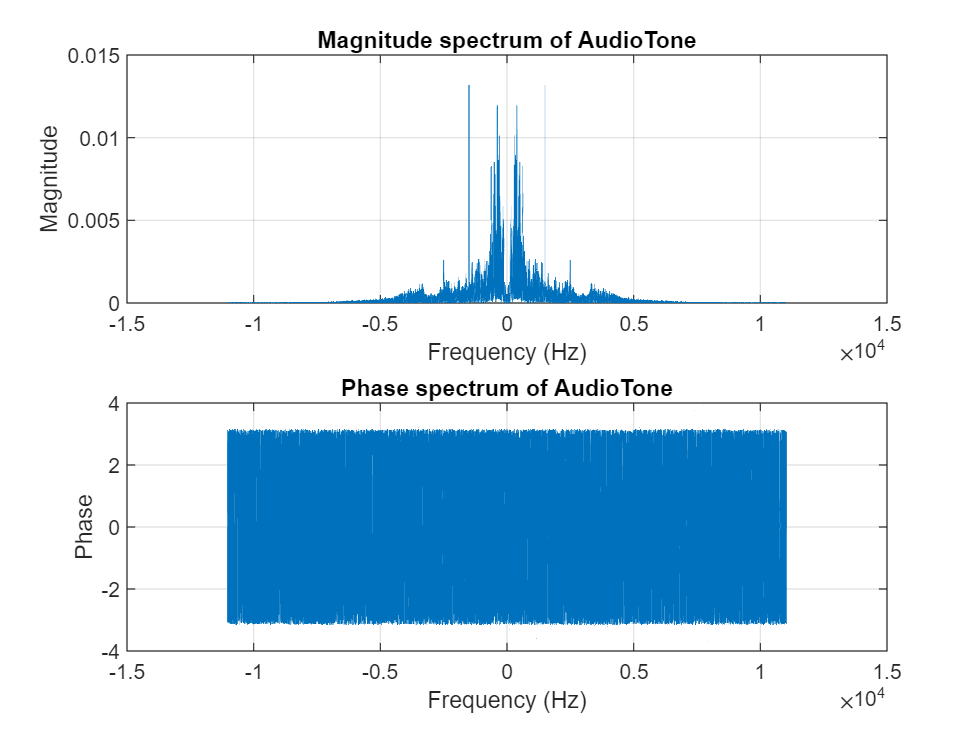

% Reading in audio file 'audioTone'
[audioTone,fs] = audioread('audio2.wav');
% sound(audioTone, fs)

% Transform audio file to frequency domain
Ts = 1/fs;
AudioTone = fftshift(fft(audioTone)) * Ts;

% Generate frequency vector f for plotting the magnitude spectrum
% in the next step
samples = length(AudioTone);
f = linspace(-fs / 2, fs / 2, samples + 1); % This is the frequency vector from -fs/2 to fs/2
f(end) = [];

% Plot the magnitude of 'AudioTone'
figure(3)
subplot(2,1,1)
plot(f, abs(AudioTone))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude spectrum of AudioTone')
grid on

% Plot the phase of 'AudioTone'
subplot(2,1,2)
plot(f, angle(AudioTone))
xlabel('Frequency (Hz)')
ylabel('Phase')
title('Phase spectrum of AudioTone')
grid on


% Recreate the tone
[~, idx] = max(abs(AudioTone))

idx = 48458

fc = abs(f(idx)); % Carrier frequency
df = f(2) - f(1); % Difference in frequency
impulseAmplitude = max(abs(AudioTone));
impulseArea = impulseAmplitude * df;
A = 2 * impulseArea; % Area under impulse is height of Dirac delta
t = linspace(0, Ts * samples, samples + 1);
t(end) = [];

tone = A * cos(2 * pi * fc * t);

% Denoise the actual signal
denoised_audioTone = audioTone.' - tone;

% play the sound
sound(denoised_audioTone,fs);
